clc; close all;
k = 4;
d = 30;
n = 5;
m = 1e6;

hmm_options.epsilon = 1/10;
hmm_options.method = "random";
hmm_options.distribution = 'Normal';

cpd_options.maxIter = 2500;
cpd_options.tol = 1e-14;
cpd_options.th_relerr = 1e-8;
cpd_options.epsilon = 1/10;

alpha = 0.1;
rho = 0.85;

[T, Os, pi, ~, ~] = generateHMM(k, d, n, hmm_options);

T_hats = cell(n,1);
O_hats = cell(n,1);

P3 = cell(n,1);
P_True = cell(n, 1);
[seq, states] = generate_multivariate_hmm_sequence(T, Os, pi, m);

for i = 1:n
    U = {};
    U{1} = (Os{i} * diag(pi) * T' / diag(T * pi'));
    U{2} = Os{i};
    U{3} = (Os{i} * T);
    P_True{i} = cpdgen(U)./sum(cpdgen(U), 'all');

    P3{i} = ProbabilityTensorGenerate(seq(i, :), 3, d);
    P3{i} = laplacian_smoothing_mle(P3{i}, 1e-6);
end

cpd_options.True_T = T;
cpd_options.True_Os = Os;
cpd_options.True_Ps = P_True;


relerror = zeros(n, cpd_options.maxIter);
Prec = zeros(n, cpd_options.maxIter);
P_uncoupled = cell(n, 1);
T_hat = zeros(k, k);
for ii = 1:n
    cpd_options.P_True = P_True{ii};
    [A, B, C, ~, output] = cpd_als_3d(P3{ii}, k, cpd_options);
    [krushkal_rank(A) krushkal_rank(B) krushkal_rank(C) k]

    P_uncoupled{ii} = cpdgen({A, B, C}) ./ sum(cpdgen({A, B, C}), 'all');
    relerror(ii, 1:length(output.relerr)) = output.relerr;
    Prec(ii, 1:length(output.Prec)) = output.Prec;

    O_hat = Stochasticize(B);
    T_hats{ii} = Stochasticize(pinv(Stochasticize(B)) * Stochasticize(C));

    Pbest = PermutationFit(T, T_hats{ii}, true);
    T_hats{ii} = Pbest * T_hats{ii} * Pbest';
    % Pbest * T_hats{ii} * Pbest'
    T_hat = T_hat + (1/n) * T_hats{ii};

    O_hats{ii} = O_hat * Pbest';
end

ans =      4     4     4     4


ans =      4     4     4     4


ans =      4     4     4     4


ans =      4     4     4     4


ans =      4     4     4     4


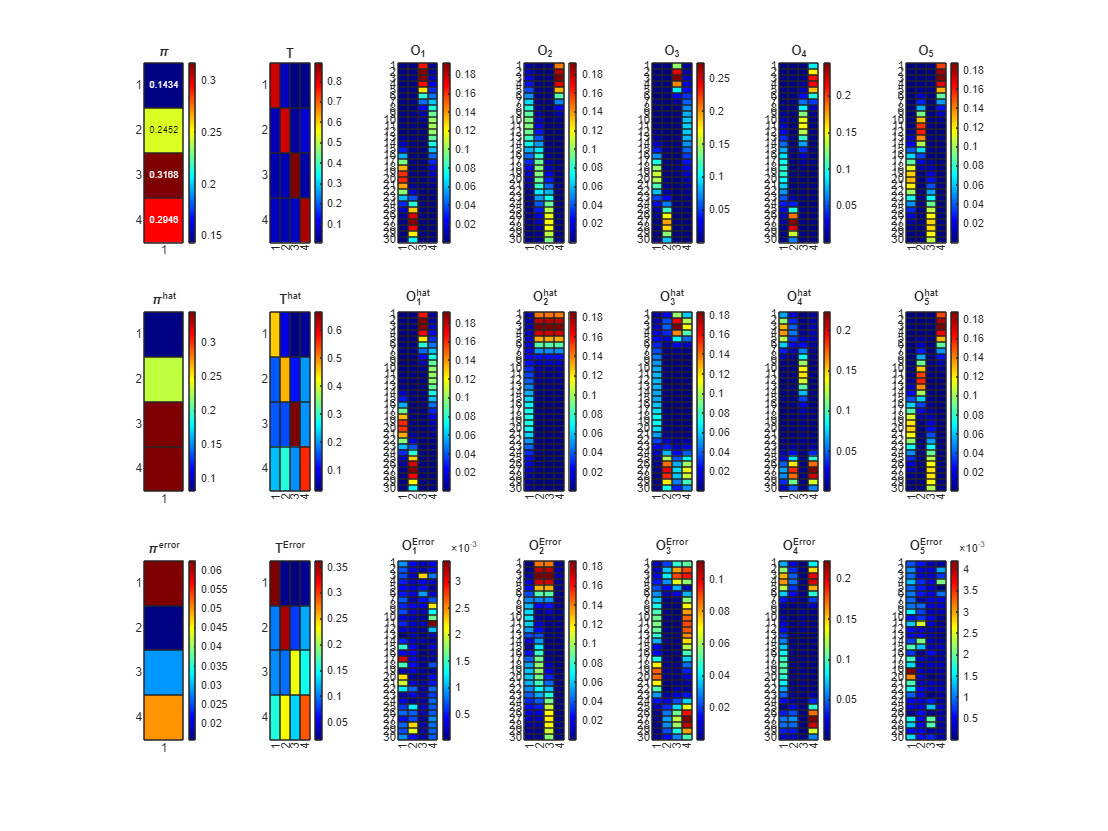

ans = 0.9931


HMMError(T, Os, T_hat, O_hats, true)

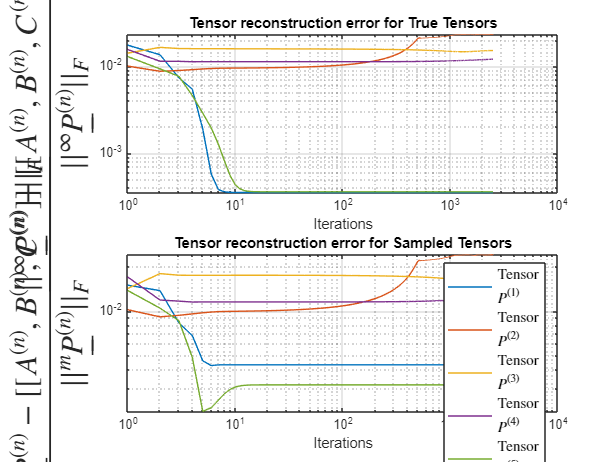


figure();
subplot(2,1,1);
loglog(Prec');
xlabel("Iterations");
ylabel("$\frac{||^\infty \underline{P}^{(n)} - [[A^{(n)}, B^{(n)} ,C^{(n)}]]||_F}{||^\infty \underline{P}^{(n)}||_F}$", "Interpreter","latex", FontSize=21)
title('Tensor reconstruction error for True Tensors');
grid on;

subplot(2, 1, 2);
loglog(relerror')
title("Tensor reconstruction error for Sampled Tensors");
xlabel("Iterations")
ylabel("$\frac{||^m \underline{P}^{(n)} - [[A^{(n)}, B^{(n)} ,C^{(n)}]]||_F}{||^m \underline{P}^{(n)}||_F}$", "Interpreter","latex", FontSize=21)
legendLabels = arrayfun(@(i) sprintf('Tensor $$ P^{(%d)}$$', i), 1:n, 'UniformOutput', false);
legend(legendLabels, 'Interpreter', 'latex', 'FontSize',10);
grid on;


[T_hat, O_hats, pi_hat, output] = multivariate_coupled_cpd_2(P3, k, d, n, alpha, rho, cpd_options);
[T_hat, O_hats, pi_hat] = remove_hmm_permutation_transition(T, T_hat, O_hats, pi_hat);



for i = 1:n
    sum(output.Ps{i} - cpdgen({O_hats{i}*diag(pi_hat)*T_hat'*inv(diag(T_hat*pi_hat)), O_hats{i}, O_hats{i}*T_hat}) ./ sum(cpdgen({O_hats{i}*diag(pi_hat)*T_hat'*inv(diag(T_hat*pi_hat)), O_hats{i}, O_hats{i}*T_hat}), 'all'), 'all')
end

ans = -3.7640e-15

ans = -1.5423e-15

ans = -2.5778e-16

ans = -3.0672e-15

ans = 1.5481e-15


for i = 1:n
    [krushkal_rank(output.A{i}) krushkal_rank(output.B{i}) krushkal_rank(output.C{i}) k]
end

ans =      4     4     4     4


ans =      4     4     4     4


ans =      4     4     4     4


ans =      4     4     4     4


ans =      4     4     4     4


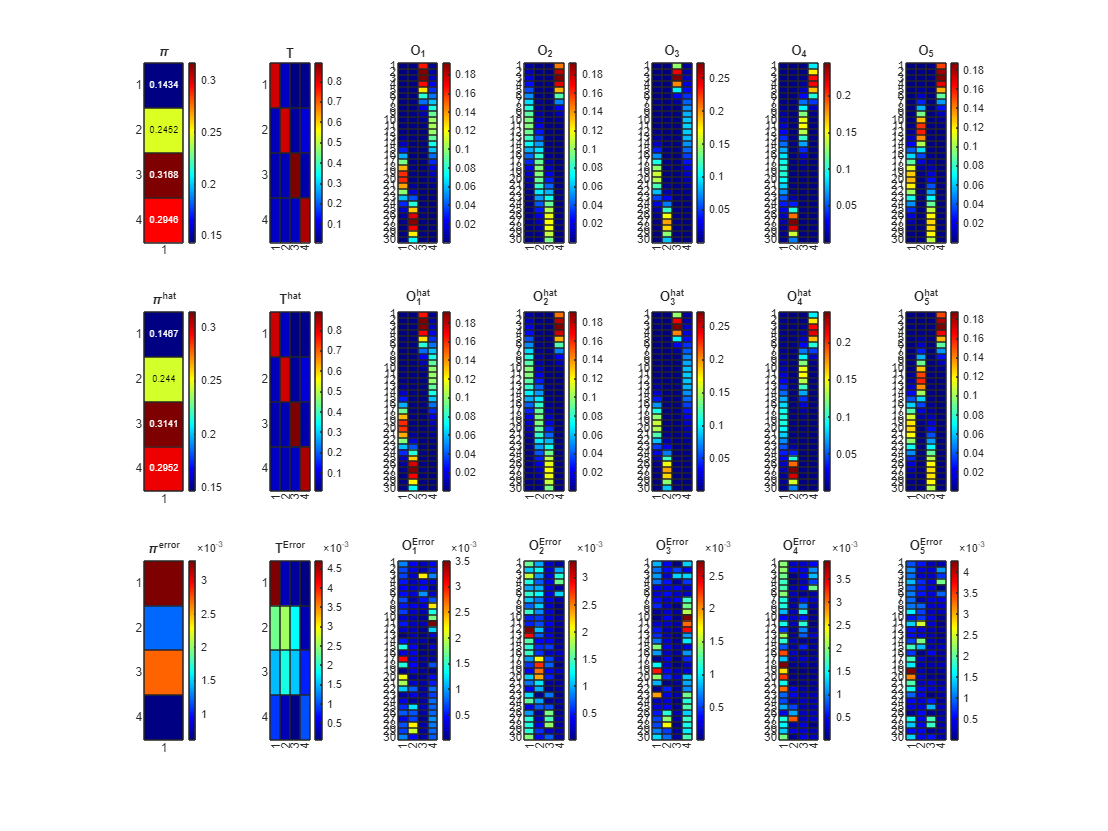

ans = 0.0189

HMMError(T, Os, T_hat, O_hats, true)

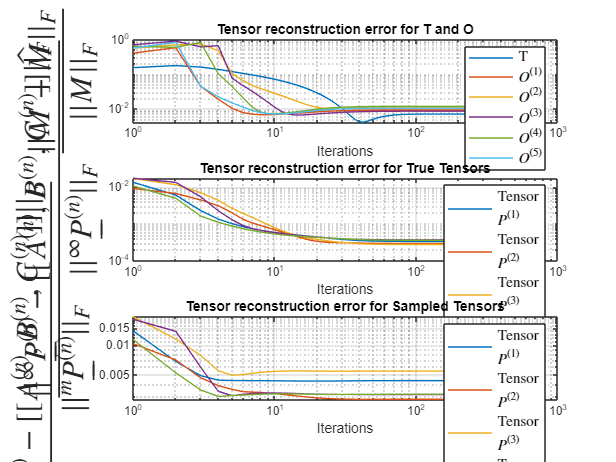


fig = figure();

subplot(3,1,1);
loglog(1:length(output.Trec), output.Trec, 1:length(output.Orec), output.Orec');
title('Tensor reconstruction error for T and O');
legendLabels = arrayfun(@(i) sprintf('$$ O^{(%d)}$$', i), 1:n, 'UniformOutput', false);
xlabel("Iterations");
ylabel("$\frac{||M - \hat{M}||_F}{||M||_F}$", "Interpreter","latex", FontSize=21)
legend(["T", legendLabels], 'Interpreter', 'latex', 'FontSize',10);
grid on;

subplot(3,1,2);
loglog(output.Prec');
title('Tensor reconstruction error for True Tensors');
xlabel("Iterations");
ylabel("$\frac{||^\infty \underline{P}^{(n)} - [[A^{(n)}, B^{(n)} ,C^{(n)}]]||_F}{||^\infty \underline{P}^{(n)}||_F}$", "Interpreter","latex", FontSize=21)
legendLabels = arrayfun(@(i) sprintf('Tensor $$ P^{(%d)}$$', i), 1:n, 'UniformOutput', false);
legend(legendLabels, 'Interpreter', 'latex', 'FontSize',10);
grid on;

subplot(3, 1, 3);
loglog(output.recerr')
title("Tensor reconstruction error for Sampled Tensors")
xlabel("Iterations")
ylabel("$\frac{||^m \underline{P}^{(n)} - [[A^{(n)}, B^{(n)} ,C^{(n)}]]||_F}{||^m \underline{P}^{(n)}||_F}$", "Interpreter","latex", FontSize=21)
legendLabels = arrayfun(@(i) sprintf('Tensor $$ P^{(%d)}$$', i), 1:n, 'UniformOutput', false);
legend(legendLabels, 'Interpreter', 'latex', 'FontSize',10);
grid on;


table = zeros(n, 6);
for i = 1:n
    table(i, 1) = norm(P_True{i} - P3{i}, 'fro');
    table(i, 2) = norm(P_True{i} - output.Ps{i}, 'fro');
    table(i, 3) = norm(P_True{i} - P_uncoupled{i}, 'fro');

    table(i, 4) = norm(output.Ps{i} - P_uncoupled{i}, 'fro');
    table(i, 5) = norm(P3{i} - P_uncoupled{i}, 'fro');
    table(i, 6) = norm(P3{i} - output.Ps{i}, 'fro');
end
table

table =     0.0044    0.0003    0.0004    0.0000    0.0043    0.0043
    0.0028    0.0003    0.0232    0.0231    0.0241    0.0028
    0.0054    0.0003    0.0152    0.0151    0.0168    0.0054
    0.0031    0.0004    0.0121    0.0119    0.0124    0.0031
    0.0032    0.0004    0.0004    0.0000    0.0032    0.0031



s = 8;

figure()
for i = 1:n
    subplot(n, s, s*(i-1)+1)
    voxel3(P_True{i})
    title("True")

    subplot(n, s, s*(i-1)+2)
    voxel3(P3{i})
    title("Sampled")

    subplot(n, s, s*(i-1)+3)
    voxel3(output.Ps{i})
    title("Coupled Estimate")

    subplot(n, s, s*(i-1)+4)
    voxel3(P_uncoupled{i})
    title("Uncoupled Estimate")

    subplot(n, s, s*(i-1)+5)
    voxel3(abs(P_True{i} - output.Ps{i}))
    title("|True - Coupled Estimate|")

    subplot(n, s, s*(i-1)+6)
    voxel3(abs(P_True{i} - P_uncoupled{i}))
    title("|True - Uncoupled Estimate|")

    subplot(n, s, s*(i-1)+7)
    voxel3(abs(P3{i} - output.Ps{i}))
    title("|Sampled - Coupled Estimate|")

    subplot(n, s, s*(i-1)+8)
    voxel3(abs(P3{i} - P_uncoupled{i}))
    title("|Sampled - Uncoupled Estimate|")
end


% figure()
% for i = 1:n
%     subplot(n, s, s*(i-1)+1)
%     voxel3(abs(P_True{i} - output.Ps{i}))
%     title("|True - Coupled Estimate|")
% 
%     subplot(n, s, s*(i-1)+2)
%     voxel3(abs(P_True{i} - P_uncoupled{i}))
%     title("|True - Uncoupled Estimate|")
% 
%     subplot(n, s, s*(i-1)+3)
%     voxel3(abs(P3{i} - output.Ps{i}))
%     title("|Sampled - Coupled Estimate|")
% 
%     subplot(n, s, s*(i-1)+4)
%     voxel3(abs(P3{i} - P_uncoupled{i}))
%     title("|Sampled - Uncoupled Estimate|")
% end




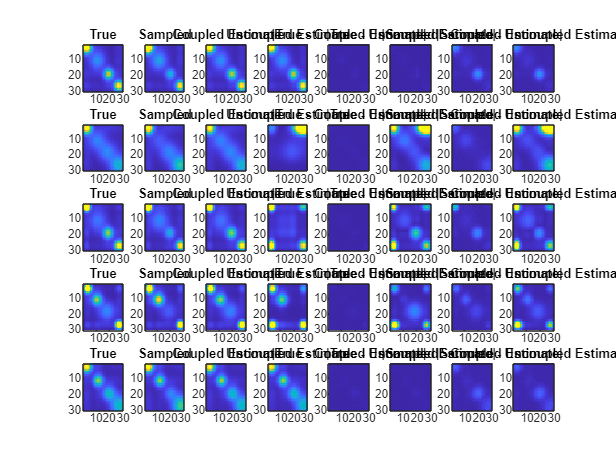

clims = [0 0.0071];

figure()
for i = 1:n
    subplot(n, s, s*(i-1)+1)
    imagesc(squeeze(sum(P_True{i}, 1)), clims)
    title("True")

    subplot(n, s, s*(i-1)+2)
    imagesc(squeeze(sum(P3{i}, 1)), clims)
    title("Sampled")

    subplot(n, s, s*(i-1)+3)
    imagesc(squeeze(sum(output.Ps{i}, 1)), clims)
    title("Coupled Estimate")

    subplot(n, s, s*(i-1)+4)
    imagesc(squeeze(sum(P_uncoupled{i}, 1)), clims)
    title("Uncoupled Estimate")

    subplot(n, s, s*(i-1)+5)
    imagesc(squeeze(sum(abs(P_True{i} - output.Ps{i}), 1)), clims)
    title("|True - Coupled Estimate|")

    subplot(n, s, s*(i-1)+6)
    imagesc(squeeze(sum(abs(P_True{i} - P_uncoupled{i}),1)), clims)
    title("|True - Uncoupled Estimate|")

    subplot(n, s, s*(i-1)+7)
    imagesc(squeeze(sum(abs(P3{i} - output.Ps{i}), 1)), clims)
    title("|Sampled - Coupled Estimate|")

    subplot(n, s, s*(i-1)+8)
    imagesc(squeeze(sum(abs(P3{i} - P_uncoupled{i}), 1)), clims)
    title("|Sampled - Uncoupled Estimate|")
end